# Entrega día 15/05

Yimin Pan G12

#### Braitenberg Internal Description 

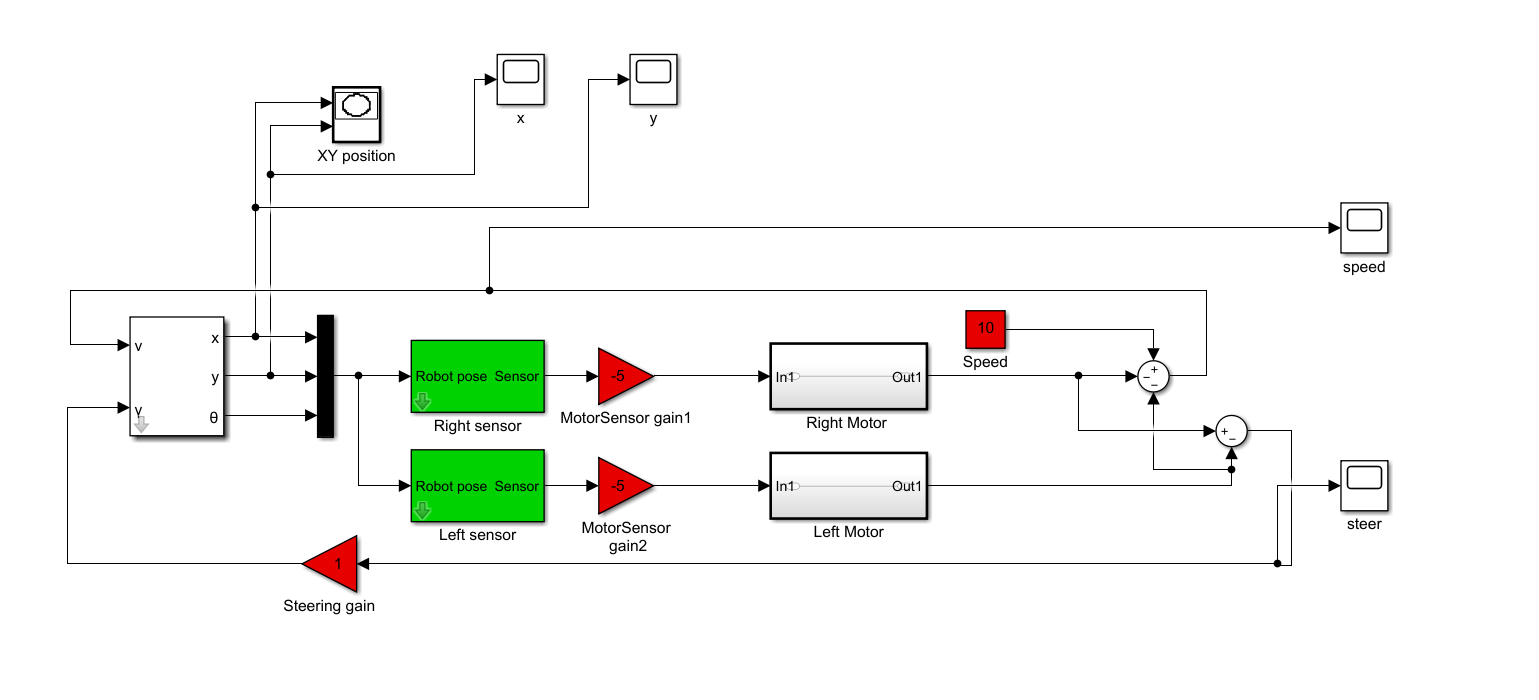

#### Ex1

a) Experiment with different starting confi gurations and control gains.

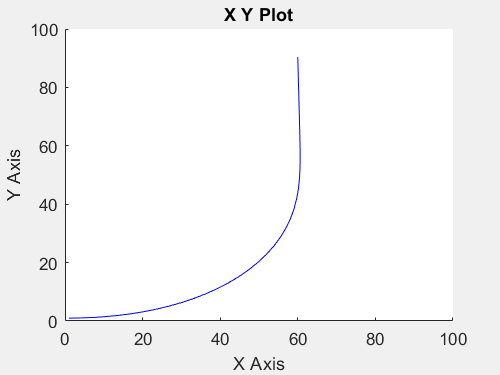

sl_braitenberg
sim('sl_braitenberg');

b) Modify the signs on the steering signal to make the vehicle light-phobic.

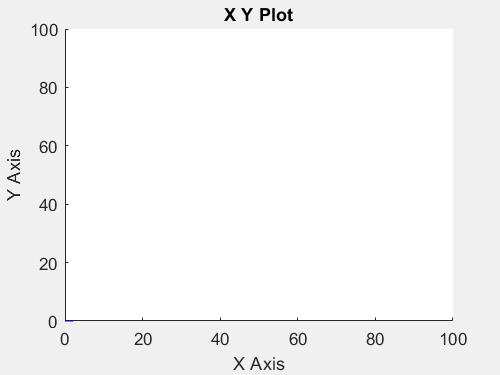

sim('sl_braitenberg');

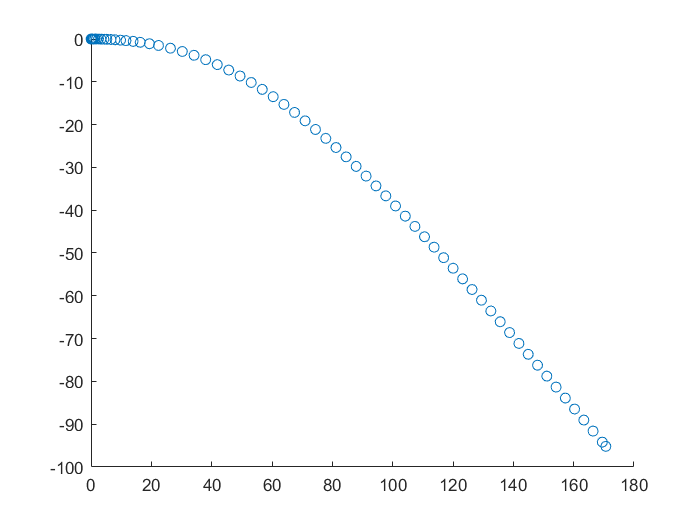

x = xout(:,1);
y = xout(:,2);
scatter(x,y);

c) Modify the sensorfield function so that the peak moves with time

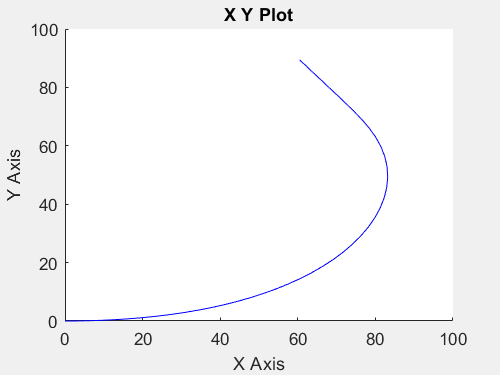

sim('sl_braitenberg');

d) The vehicle approaches the maxima asymptotically. Add a stopping rule so that the vehicle stops when the when either sensor detects a value greater than 0.95.

function sensor = sensorfield(x, y)

    xc = 60; yc = 90;

    sensor = 200./((x-xc).^2 + (y-yc).^2 + 200);

    if (sensor >= 0.95)

        sensor = 1;

    end 

****when both sensor outputs 1, then v = 2-S_left-S_right = 0, the vehicle stops.

e) Create a scalar field with two peaks. Can you create a starting pose where the robot gets confused?

Giving a starting point [100,100] further than the goal [60,90] we can confuse the robot as in the second plot shows, the robot tries to reach at [240,-40].

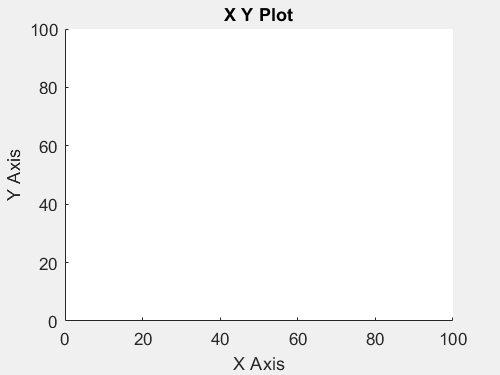

sim('sl_braitenberg');

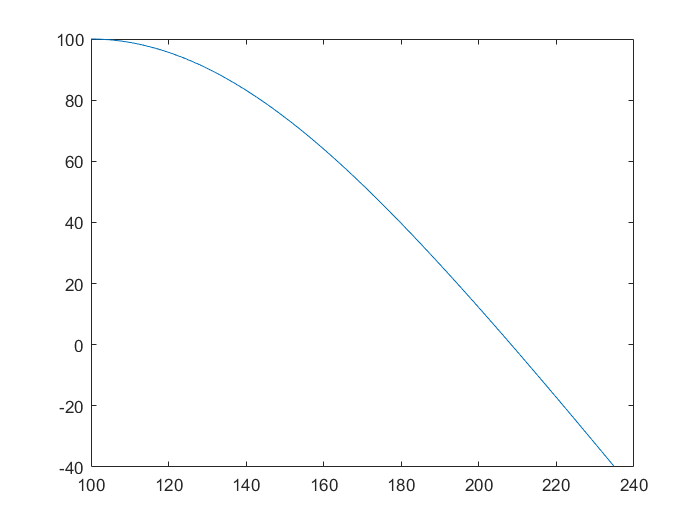

plot(xout(:,1),xout(:,2));

#### Ex2

a) Using the function makemap create a new map to challenge bug2. Try different starting points.

makemap:
  left button, click and drag to create a rectangle
  or type the following letters in the figure window:
  p - draw polygon
  c - draw circle
  e - erase map
  u - undo last action
  q - leave editing mode


point1 =    11.2735   90.3364


point2 =    90.8315   89.6355


point1 =    89.5424   86.8318


point2 =    89.7265   12.2991


point1 =     9.8002   81.6916


point2 =    80.5184   79.5888


point1 =    79.7818   75.6168


point2 =    79.5976   22.3458


point1 =    80.8867   79.8224


point2 =    80.7026   74.2150


point1 =    10.1685   70.0093


point2 =    10.5368   10.8972


point1 =     9.9843   10.6636


point2 =    40.0028   10.4299


point1 =    40.3711   40.5701


point2 =    40.1869    6.4579


point1 =    18.6400   42.4393


point2 =    40.3711   40.3364


point1 =    19.5608   44.0748


point2 =    20.4816   61.5981


point1 =    20.6657   61.1308


point2 =    60.0764   60.4299


point1 =    60.0764   58.7944


point2 =    60.0764   21.1776


point1 =    50.3158   20.7103


point2 =    59.7081   20.7103


point1 =    50.3158   30.0561


point2 =    50.5000   22.8131


point1 =    50.3158   23.0467


point2 =    50.3158   18.8411


point1 =    19.5608   44.3084


point2 =    20.4816   40.3364


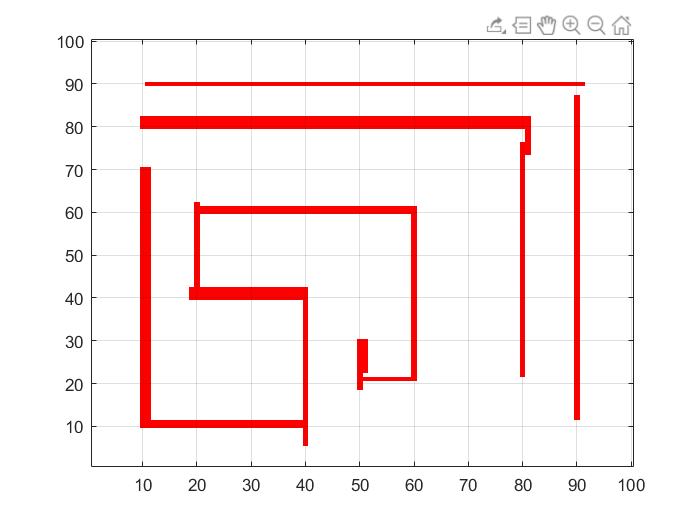

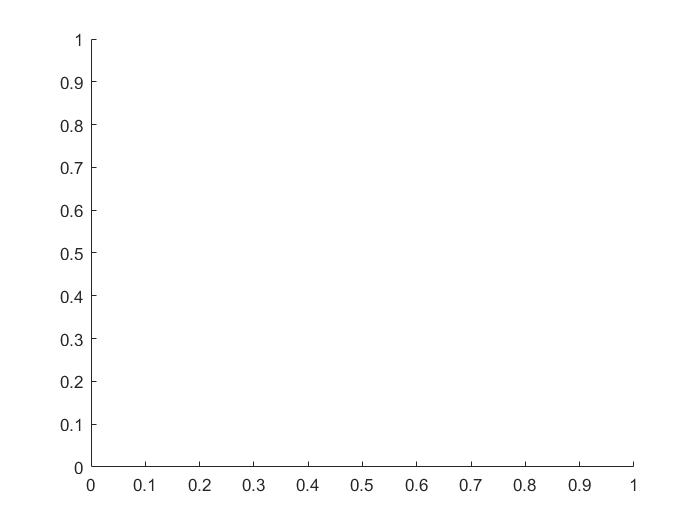

map = makemap(100); % map of size 100x100

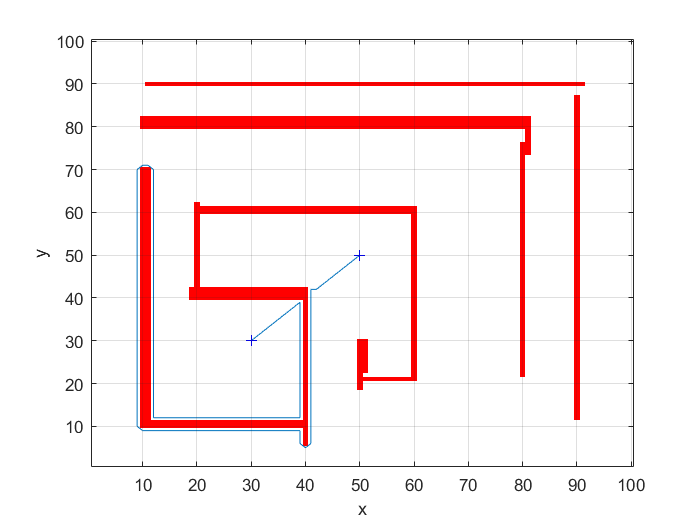

startpoint = [30,30];
goal = [50, 50];
bug = Bug2(map);
bug.plot();
hold on;
traj = bug.query(startpoint, goal);
plot(traj(:,1), traj(:,2));
hold on;
scatter(startpoint(1), startpoint(2), 'blue+');
scatter(goal(1), goal(2), 'blue+');
hold off

b) Create an obstacle map that contains a maze. Can bug2 solve the maze?

makemap:
  left button, click and drag to create a rectangle
  or type the following letters in the figure window:
  p - draw polygon
  c - draw circle
  e - erase map
  u - undo last action
  q - leave editing mode


point1 =     9.8002   10.1963


point2 =    10.5368   91.5047


point1 =    19.7449    9.2617


point2 =    19.7449   81.2243


point1 =    20.2974   80.9907


point2 =    79.5976   79.8224


point1 =    11.2735   90.5701


point2 =    90.2790   90.3364


point1 =    90.2790   89.8692


point2 =    90.0948    8.5607


point1 =    79.9659   70.0093


point2 =    79.9659   31.9252


point1 =    20.4816    9.7290


point2 =    89.3582   10.1963


point1 =    30.2422   19.5421


point2 =    80.8867   20.2430


point1 =    19.7449   70.7103


point2 =    79.9659   70.0093


point1 =    29.8738   60.1963


point2 =    29.6897   20.7103


point1 =    30.2422   60.4299


point2 =    70.0212   61.3645


point1 =    70.0212   61.1308


point2 =    69.8370   32.3925


point1 =    41.8444   29.8224


point2 =    70.7578   30.5234


point1 =    41.2919   31.2243


point2 =    39.8186   49.4486


point1 =    22.6915   41.2710


point2 =    23.7965   26.0841


point1 =    41.8444   49.9159


point2 =    59.3398   49.4486


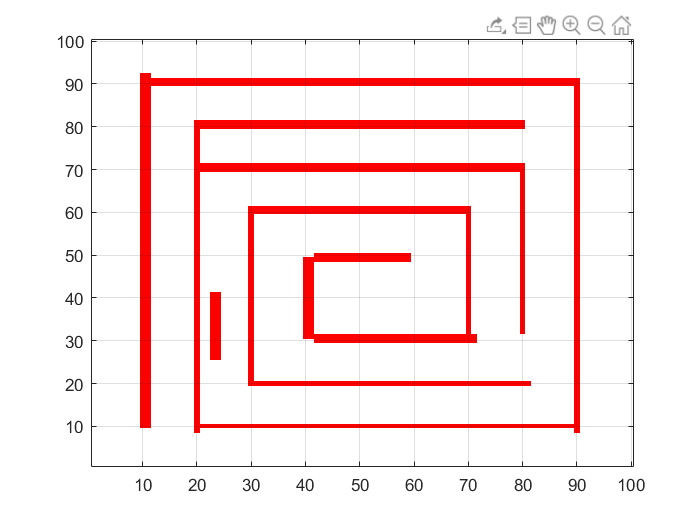

map = makemap(100); % map of size 100x100

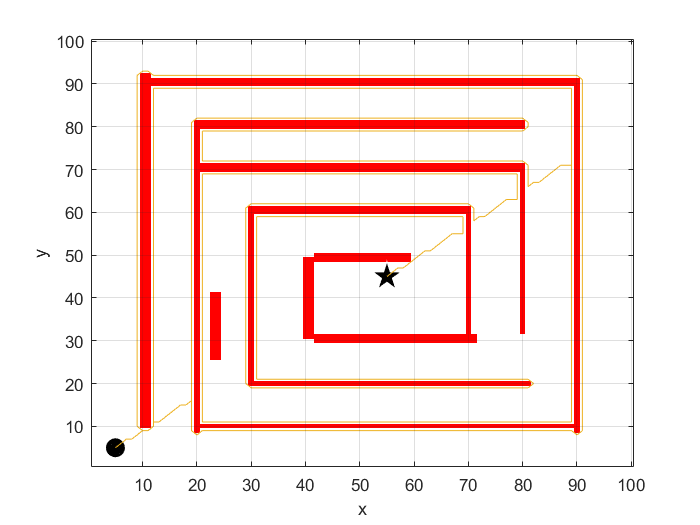

startpoint = [5,5];
goal = [55, 45];
bug = Bug2(map);
traj = bug.query(startpoint, goal);
bug.plot();
hold on;
plot(traj(:,1), traj(:,2));
hold off

The algorith is able to reach the goal

c) Experiment with different start and goal locations.

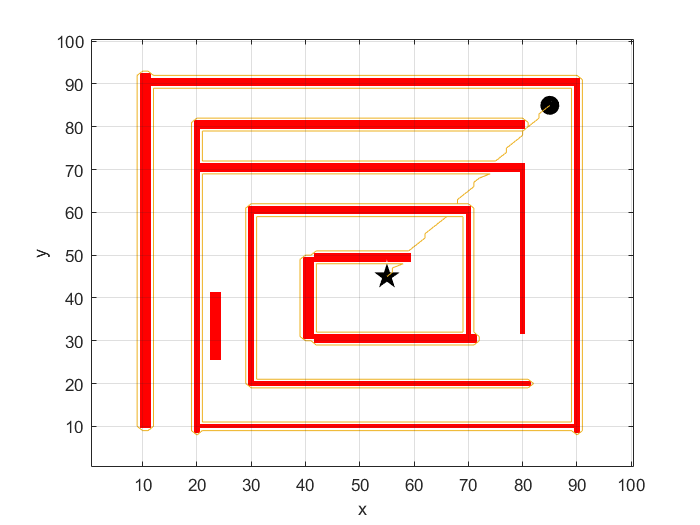

startpoint = [85,85];
goal = [55, 45];
bug = Bug2(map);
traj = bug.query(startpoint, goal);
bug.plot();
hold on;
plot(traj(:,1), traj(:,2));
hold off

d) Create a bug trap. Make a hollow box, and start the bug inside a box with the goal outside. What happens?

makemap:
  left button, click and drag to create a rectangle
  or type the following letters in the figure window:
  p - draw polygon
  c - draw circle
  e - erase map
  u - undo last action
  q - leave editing mode


point1 =    30.2422   79.3551


point2 =    30.0580   22.1121


point1 =    29.8738   21.8785


point2 =    70.3895   20.4766


point1 =    70.3895   20.2430


point2 =    70.0212   80.0561


point1 =    30.0580   79.3551


point2 =    69.1004   80.2897


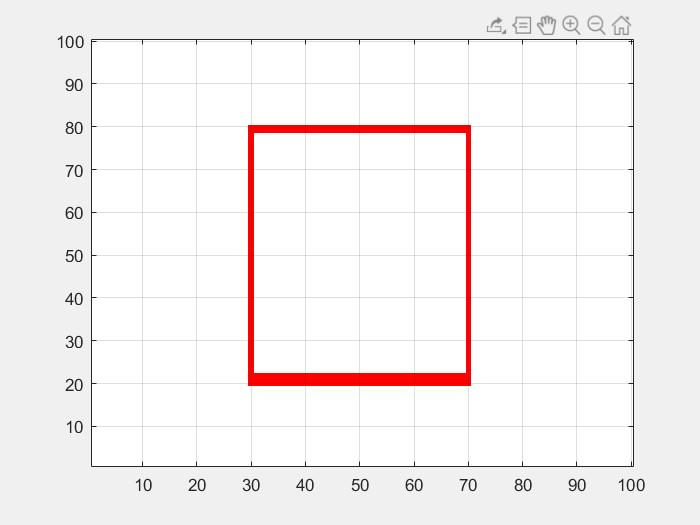

map = makemap(100); % map of size 100x100

startpoint = [50,50];
goal = [90, 90];
bug = Bug2(map);
traj = bug.query(startpoint, goal);

Error using Bug2/next (line 261)
robot is trapped

Error in Bug2/query (line 160)
                robot = bug.next(robot);

Robot is trapped

e) Modify bug2 to change the direction it turns when it hits an obstacle.

makemap:
  left button, click and drag to create a rectangle
  or type the following letters in the figure window:
  p - draw polygon
  c - draw circle
  e - erase map
  u - undo last action
  q - leave editing mode


point1 =    19.9291   78.4206


point2 =    19.9291   19.3084


point1 =    19.9291   19.3084


point2 =    59.3398   19.5421


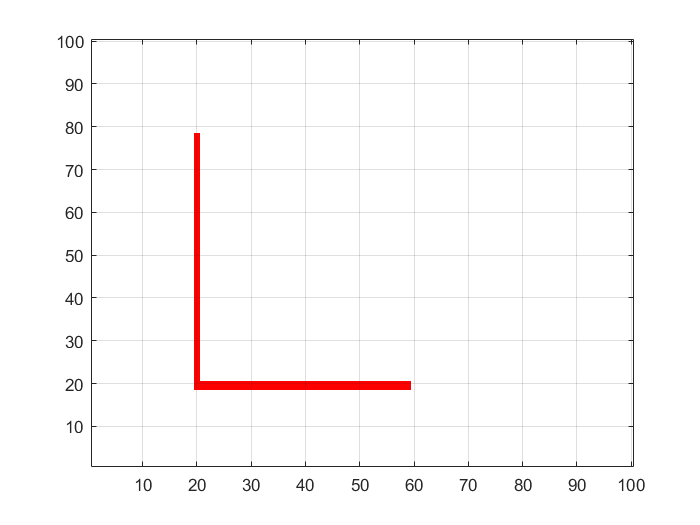

map = makemap(100); % map of size 100x100

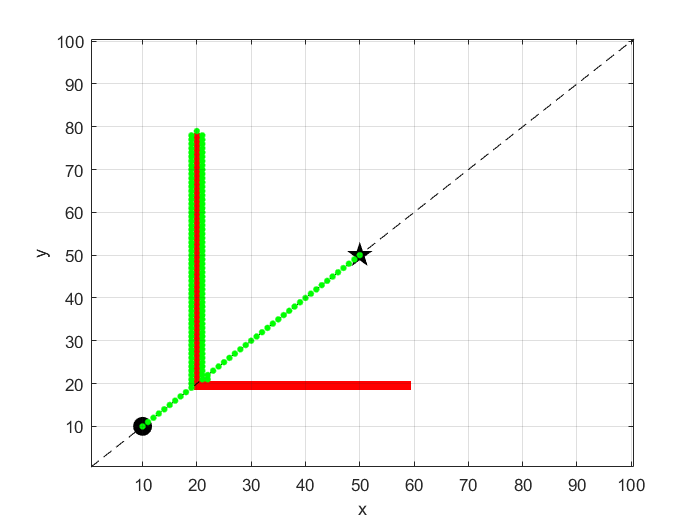

startpoint = [10,10];
goal = [50, 50];
bug = Bug3(map);
traj = bug.query(startpoint, goal, 'animate');

bug.edge = edgelist(bug.occgridnav == 0, robot) **=====>** bug.edge = edgelist(bug.occgridnav == 0, robot, 1); 

-we change the order we get the list of edges in counterclockwise direction ( without the parameter 1, by default is clockwise).